clear
clc

x1 = RandomVariable.RV('dist',normrnd(-2,0.5,[1,2000]),'res',500);
x2 = RandomVariable.RV('dist',gamrnd(3,1,[1,2000]),'res',500);

xm = -10:0.05:10;

figure
x1.plot(xm)

hold on
x2.plot(xm)

tic
x3 = x1.*x1;
toc

Elapsed time is 0.027822 seconds.


x3.plot(xm)

tic
x4 = (x1.*x2).^x3;
toc

Elapsed time is 0.017256 seconds.


x4.plot(xm)

tic
x5 = x4.*x4;
toc

Elapsed time is 0.015661 seconds.


x5.plot(xm)

tic
x6 = x5./x2;
toc

Elapsed time is 0.010889 seconds.


x6.plot(xm)

tic
x7 = acos(x6);
toc

Elapsed time is 0.018796 seconds.


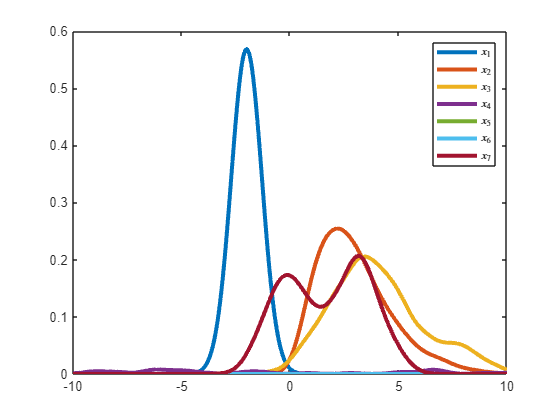

x7.plot(xm)

legend('$x_1$','$x_2$','$x_3$','$x_4$','$x_5$','$x_6$','$x_7$','interpreter','latex')

X{1} = x2;
X{2} = x2;

tic
[TT,YY] = ODE.Simulator(@(t,y) ODE.test.PredatorPreyRHS(t,y,0.8,0.9,1.4,0.8),X,@ODE.rk38,0, 10, 0.001);
toc

Elapsed time is 24.826251 seconds.


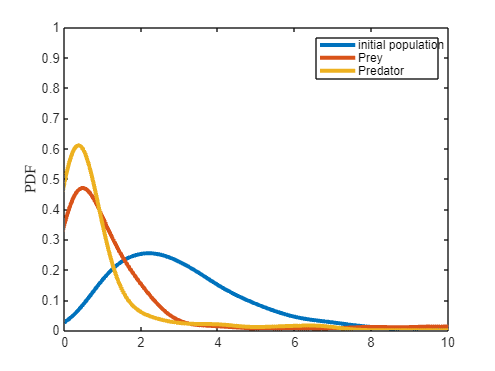

for i = 1:100:size(TT,1)
    y1 = RandomVariable.RV('dist',YY(1,i,:),'res',500);
    y2 = RandomVariable.RV('dist',YY(2,i,:),'res',500);

    figure(1)
    clf(1)
    x2.plot(xm)
    hold on
    y1.plot(xm)
    y2.plot(xm)
    ylim([0 1])
    xlim([0 10])
    legend('initial population','Prey','Predator')
    ylabel('PDF','Interpreter','latex')
    drawnow

    exportgraphics(gcf,'PP_ODE_RV_Distribution2.gif','Append',true);

    pause(0.01)
end